# Sintonía de un controlador PID

## Método: Ubicación de polos

Ejemplo:


$$\mathrm{Gp}\left(z\right)=\frac{0\ldotp 006432z^2 -0\ldotp 003896z+0\ldotp 0005106}{z^2 -0\ldotp 4705z-0\ldotp 3411}z^{-1}$$


Requerimientsos del sistema de control en LC


$$\begin{array}{l}
M_p <0\ldotp 1\\
t_{{\mathrm{ss}}_{\mathrm{LC}} } <0\ldotp 5t_{{\mathrm{ss}}_{\mathrm{LA}} } 
\end{array}$$


close all
clear all

s = tf('s');

T = 0.05;
z = tf('z',T);
Gpz = (0.006432*z^2 - 0.003896*z + 0.0005106)...
    * z^-1 / (z^2 - 0.4705*z - 0.3411)

Gpz =
 
  0.006432 z^2 - 0.003896 z + 0.0005106
  -------------------------------------
       z^3 - 0.4705 z^2 - 0.3411 z
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


step(Gpz*100)

Gz = (0.006432*z^2 - 0.003896*z + 0.0005106)...
    / (z^2 - 0.4705*z - 0.3411)

Gz =
 
  0.006432 z^2 - 0.003896 z + 0.0005106
  -------------------------------------
         z^2 - 0.4705 z - 0.3411
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


Gs = d2c(Gz, 'tustin')

Gs =
 
  0.009597 s^2 + 0.4194 s + 4.316
  -------------------------------
        s^2 + 95 s + 266.9
 
Continuous-time transfer function.
Model Properties


theta = 1;
Gps = Gs

Gps =
 
  0.009597 s^2 + 0.4194 s + 4.316
  -------------------------------
        s^2 + 95 s + 266.9
 
Continuous-time transfer function.
Model Properties


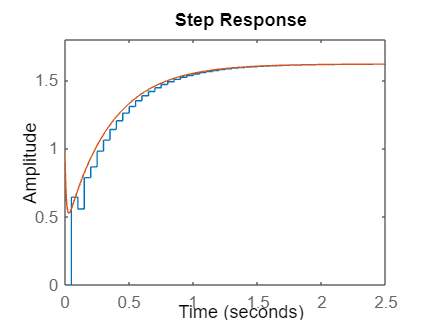

hold on
step(Gps*100)


MpLA = (8.66-6) / 6; % leido de la grafica
z = double(vpasolve(exp(-(pi*z)/sqrt(1-z^2))==MpLA,z));

Incorrect number or types of inputs or outputs for function 'sqrt'.

tp = 3.32; % leido de la grafica
wn = pi/(tp*sqrt(1-z^2));
tssLA = pi / (z*wn);


$$\begin{array}{l}
M_p =e^{-\frac{\zeta_{\textrm{LCr}} \pi }{\sqrt{\left(1-{\zeta_{\textrm{LCr}} }^2 \right)}}\;} \\
t_{{\textrm{ss}}_{\textrm{LCr}} } =\frac{\pi }{\zeta_{\textrm{LCr}} \omega_{n_{\textrm{LCr}} } }
\end{array}$$


Mp = 0.1;
syms zr
zr = double(vpasolve(exp(-(pi*zr)/sqrt(1-zr^2))==Mp,zr))
tssLC = 0.5*tssLA;
wnr = pi/(tssLC*zr)
alpha = 2*zr*wnr

%%% Calculo de PID continuo %%%
syms Kp Taud Taui
EQ1_TEO = 0.5 + 6*Kp*Taud;
EQ2_TEO = 1 + 6*Kp;
EQ3_TEO = 6*Kp/Taui;

EQ1_REQ = 2*zr*wnr + alpha;
EQ2_REQ = wnr^2 + 2*alpha*zr*wnr;
EQ3_REQ = alpha*wnr^2;

PID = vpasolve([EQ1_TEO==EQ1_REQ,EQ2_TEO==EQ2_REQ,...
    EQ3_TEO==EQ3_REQ],[Kp, Taud, Taui]);
Kp = double(PID.Kp)
Taud = double(PID.Taud)
Taui = double(PID.Taui)

T = 0.5; % sampling time
Kpz = Kp - (Kp*T)/(2*Taui)
Kiz = Kp*T/Taui
Kdz = Kp*Taud/T

Gpz = c2d(Gps,T)
Gpz_num = Gpz.Numerator{1,1};
Gpz_den = Gpz.Denominator{1,1};